# ばね-マス-ダンパ系 振動シミュレーション

運動方程式: $m\ddot{x} + c\dot{x} + kx = 0$

このLive Scriptでは、ばね-マス-ダンパ系の自由振動を数値シミュレーションします。 パラメータを変更してグラフの変化を観察してください。

**使い方**

- 下の「パラメータ設定」セクションの数値を直接書き換えて実行する

- または Live Editor の「挿入」→「コントロール」→「スライダー」で 各変数にスライダーを追加すると、動的に変化を確認できます

## パラメータ設定

ここの値を変更するか、各行にスライダーを追加してください。

m    = 1.0;   % 質量 [kg]       ← スライダー推奨範囲: 0.1 〜 5.0, ステップ: 0.1
k    = 10.0;  % ばね定数 [N/m]  ← スライダー推奨範囲: 1.0 〜 50.0, ステップ: 0.5
zeta = 0.3;   % 減衰比 [-]      ← スライダー推奨範囲: 0.01 〜 2.5,  ステップ: 0.01

パラメータから系の特性を計算します。

omega_n = sqrt(k / m);          % 固有角周波数 [rad/s]
c       = 2 * zeta * sqrt(m*k); % 減衰係数 [N·s/m]

fprintf('固有角周波数  ω_n = %.3f rad/s\n', omega_n);

固有角周波数  ω_n = 3.162 rad/s


fprintf('固有振動数    f_n = %.3f Hz\n',    omega_n / (2*pi));

固有振動数    f_n = 0.503 Hz


fprintf('減衰係数      c   = %.3f N·s/m\n', c);

減衰係数      c   = 1.897 N·s/m



if zeta < 1
    fprintf('減衰状態: 不足減衰（振動しながら収束）\n');
elseif abs(zeta - 1) < 1e-6
    fprintf('減衰状態: 臨界減衰（振動せず最速で収束）\n');
else
    fprintf('減衰状態: 過減衰（振動せずゆっくり収束）\n');
end

減衰状態: 不足減衰（振動しながら収束）


初期条件: $x(0) = 1$ m（1m引っ張って離す）、$\dot{x}(0) = 0$ m/s

x0    = [1.0; 0.0];                                  % [変位; 速度]
tspan = [0, max(6, 4*pi / max(omega_n, 0.1))];       % 十分な観測時間

% 状態方程式: dy/dt = [y2; -(c/m)*y2 - (k/m)*y1]
odefun = @(t, y) [y(2); -(c/m)*y(2) - (k/m)*y(1)];

[t, y] = ode45(odefun, tspan, x0);

## グラフ表示

変位の時間応答を描画します。

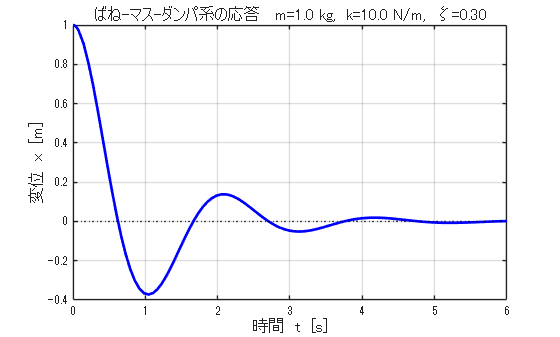

figure;
plot(t, y(:,1), 'b-', 'LineWidth', 2);
yline(0, 'k:', 'LineWidth', 1);

xlabel('時間  t  [s]',  'FontSize', 12);
ylabel('変位  x  [m]',  'FontSize', 12);
title(sprintf('ばね-マス-ダンパ系の応答   m=%.1f kg,  k=%.1f N/m,  ζ=%.2f', ...
    m, k, zeta), 'FontSize', 12);
grid on;
xlim([0, tspan(end)]);

## （参考）3パターン比較

不足減衰 / 臨界減衰 / 過減衰を同時にプロットして違いを確認します。

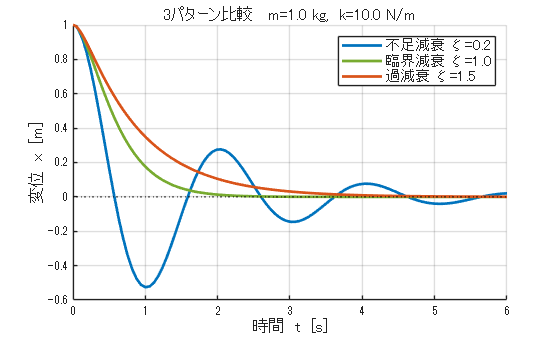

zeta_list  = [0.2, 1.0, 1.5];
label_list = {'不足減衰 ζ=0.2', '臨界減衰 ζ=1.0', '過減衰 ζ=1.5'};
color_list = {[0 0.45 0.74], [0.47 0.67 0.19], [0.85 0.33 0.10]};

figure;
hold on;
for i = 1:length(zeta_list)
    c_i = 2 * zeta_list(i) * sqrt(m * k);
    f_i = @(t,y) [y(2); -(c_i/m)*y(2) - (k/m)*y(1)];
    [t_i, y_i] = ode45(f_i, [0, 6], x0);
    plot(t_i, y_i(:,1), 'LineWidth', 2, ...
        'Color', color_list{i}, 'DisplayName', label_list{i});
end
hold off;
yline(0, 'k:', 'LineWidth', 1, 'HandleVisibility', 'off');
xlabel('時間  t  [s]', 'FontSize', 12);
ylabel('変位  x  [m]', 'FontSize', 12);
title(sprintf('3パターン比較   m=%.1f kg,  k=%.1f N/m', m, k), 'FontSize', 12);
legend('Location', 'northeast', 'FontSize', 11);
grid on;